**SISO Mixed Sensitivity Revisited**

Let's use our new understanding of the robust performance problem to design a controller for the uncertain mass spring damper system.

Build the model and generate the uncertainty weight.

m = ureal('m',2,'Range',[1,3]); 
k = ureal('k',100,'Percentage',20);
c = ureal('c',10,'PlusMinus',5);
G = tf(1,[m c k]);
Gvec = usample(G,100);
[P,info] = ucover(Gvec,G.NominalValue,4);
Wt = info.W1;  %Extract the weight

Now I'll maximize the crossover frequency with a standard first order sensitivity weight.

wh = 1000;  %Just guessing at this...we'll see if it fails
wl = 0;
w_try = wh;  %Just for simplicity
w_new = 1/2*(wh+wl);
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    [K,CL,GAM] = mixsyn(G,Wp,[],Wt);
    if GAM<1%/sqrt(2)
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end

Now plot the achieved sensitivity functions for the uncertain plant vs the sensitivity weight.

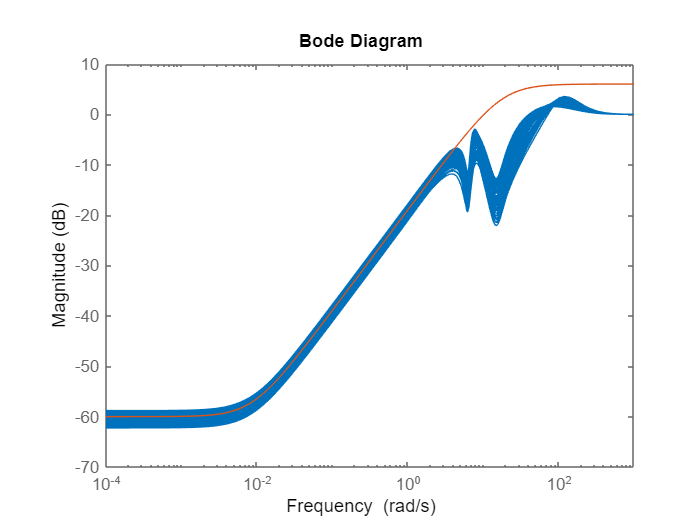

S = 1/(1+G*K);
Svec = usample(S,100);
bodemag(Svec,1/Wp)

We're not quite making it.  That's for two reasons - 1.)  the mixed sensitivity approach is not conservative for RP.  We can make it conservative by limiting the infinity norm to $1/\sqrt{2}$.  2.)  the samples we used for *ucover* aren't the same as those we used to evaluate it.  That's a tougher thing to fix, but as we increase the number of samples used we should do better.

HOWEVER, it should be noted that mixed sensitivity IS conservative for RS.  

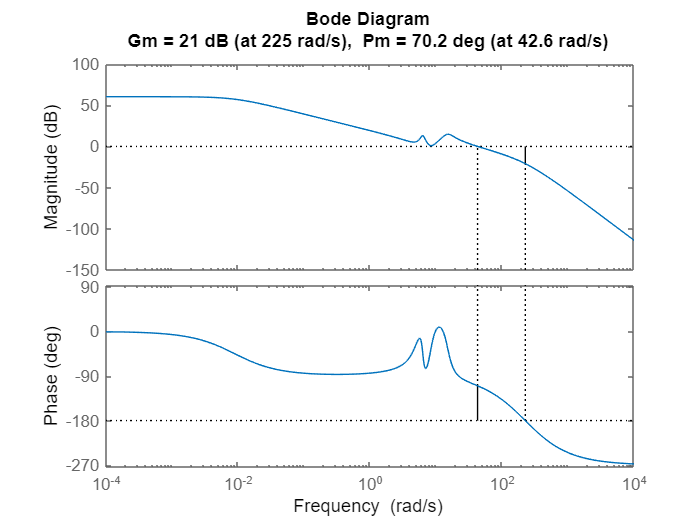

margin(G.NominalValue*K)